# 如何判断模型哈密顿量在时间反演不动点的宇称？

## 1 基组选取

基组选取，是模型研究的第一步，这里我们以参考文献 [1] 章 III.B. 给出的简化四带模型为例。这一基组其实和著名的BHZ模型的基组是相同的，Basis类已经内置了快捷创建方法。当然作为一个教程，我们还是优先说明常规的创建方法。

为了创建一个基函数对象，如果J为整数，仅需要输入J与M即可。如果J为半整数，除了J与M之外，我们还需要显式指明这个基函数的宇称。这是因为，半整数的J，显然对应于电子轨道与电子自旋的耦合态，宇称算符对自旋部分没有影响，因此整个电子波函数的宇称由轨道波函数所决定。轨道波函数可由球谐函数所描述，轨道量子数 L=0，1，2……的奇偶，就对应着球谐函数中自变量xyz的阶数。在直角坐标系下，宇称算符的效果使得xyz坐标反号，因此偶数阶自变量会消去负号，奇数阶自变量会提出一个符号，导致整体波函数反号。因此，s、d轨道为偶宇称，p、f轨道为奇宇称。如 J=3/2 的态，既可能是 J=2-1/2，也可能是 J=1+1/2，现在容易理解，这两种情况对应的宇称相反，所以必须显式指明。

最后提醒一个细节，输入多个基函数时需要使用分号而不是逗号，以将它们排列为列向量形式

Basis_WZJ = Basis([...
    Spin(1/2,+1/2,'parity',+1);
    Spin(3/2,+3/2,'parity',-1);
    Spin(1/2,-1/2,'parity',+1);
    Spin(3/2,-3/2,'parity',-1)]);
% Basis_WZJ = Basis('BHZ');

## 2 模型搭建

参考文献 [1] 中提出了两种可能的 Cd3As2 结构，但最新的相关研究倾向于认为 Cd3As2 属于 142 号空间群，该空间群下的布里渊区和电子能带与文中 structure II 类似，但保留了空间反演对称性。同时我们希望研究该体系被微扰打开带隙后的性质，所以这里参数的选取与原文略有不同

% pauli matrices
sigma_0 = pauli_matric(0); sigma_x = pauli_matric(1); sigma_y = pauli_matric(2); sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0); tau_x   = pauli_matric(1); tau_y   = pauli_matric(2); tau_z   = pauli_matric(3);
% 
syms C0 C1 C2 M0 M1 M2 A B1 real;
syms k_x k_y k_z real;
H_wzj = HK(4,2);
ek = C0 + C1*k_z^2 + C2*(k_x^2+k_y^2);
Mk = M0 - M1*k_z^2 - M2*(k_x^2+k_y^2);
%%
H_wzj = H_wzj ...
    + Term( Mk,       tau_0 * sigma_z)...
    + Term( ek,       tau_0 * sigma_0)...
    + Term( B1 * k_z, tau_x * sigma_x)...
    + Term( A  * k_x, tau_z * sigma_x)...
    + Term(-A  * k_y, tau_0 * sigma_y)...
    ;

Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


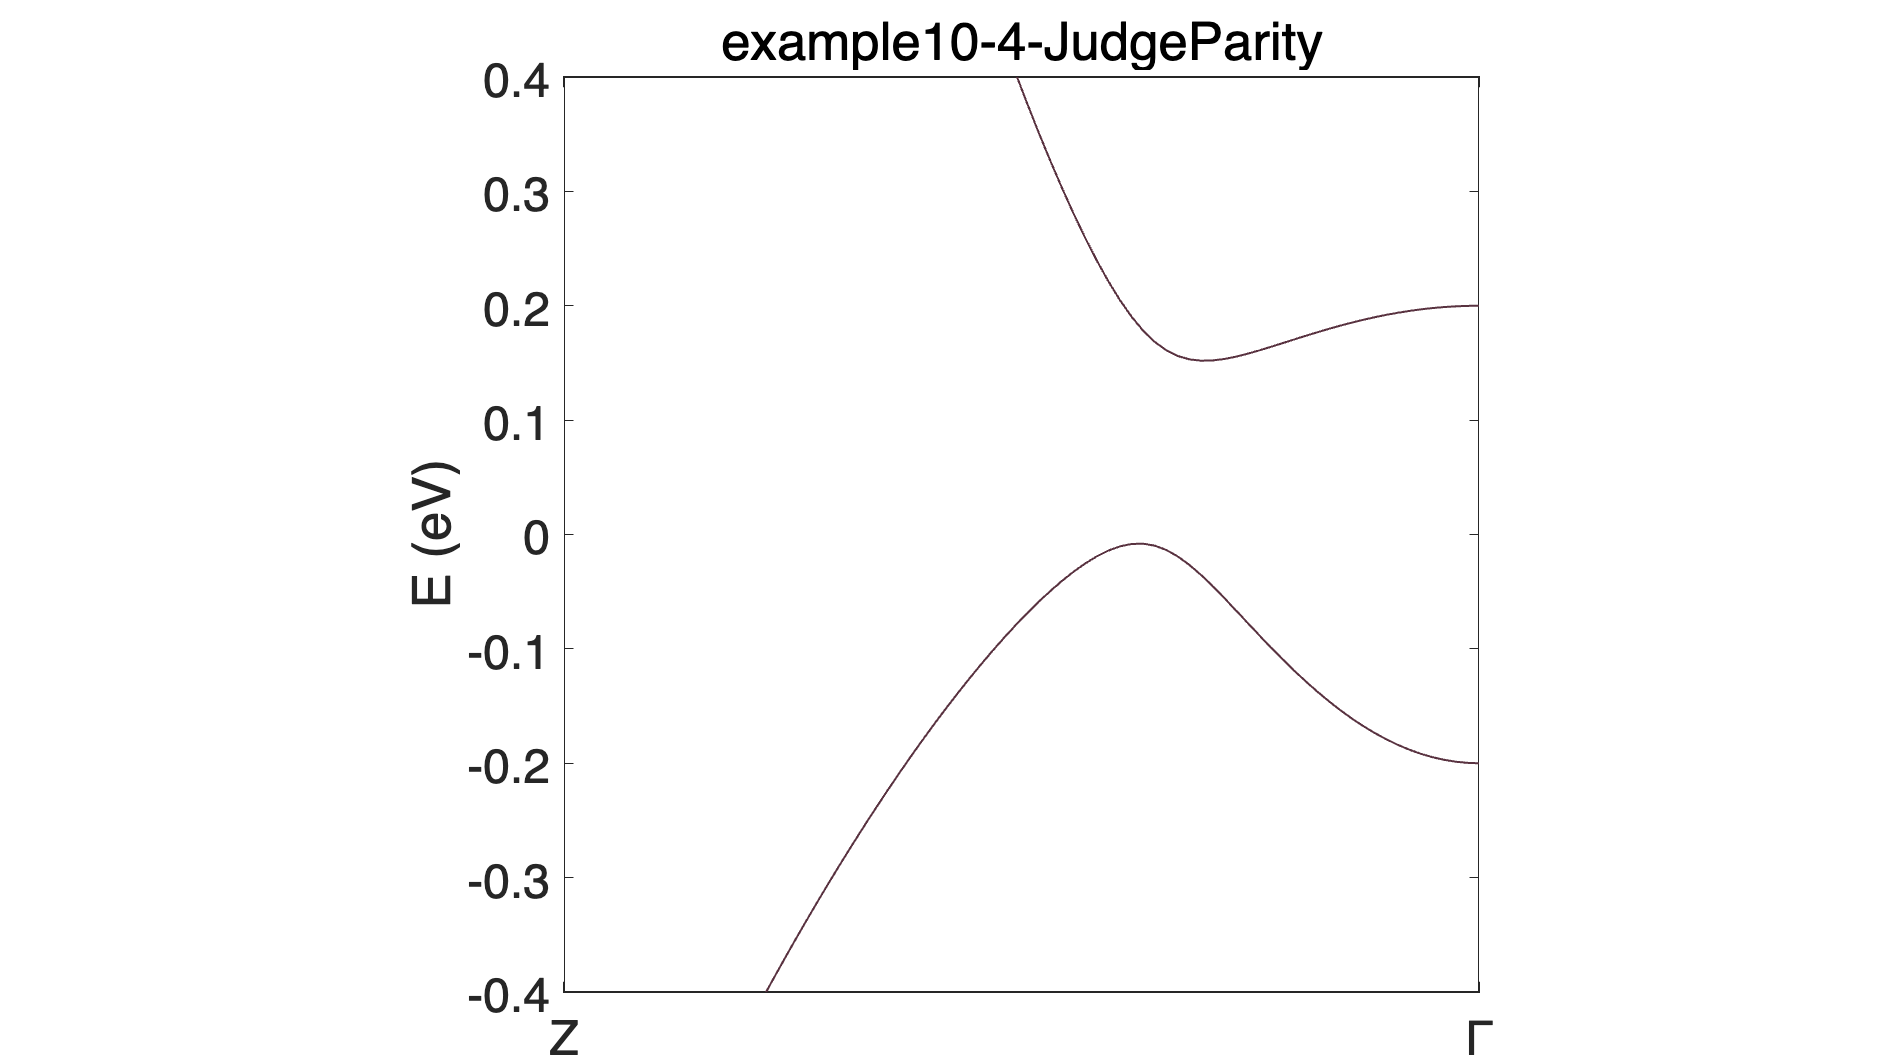

C0 = 0;
C1 = 0.4;
C2 = 0.4;
M0 = 0.2;
M1 = 1;
M2 = M1;
A  = 1;
% B1 = 0;
B1 = 0.2;

H_wzj_n = H_wzj.Subsall();
EIGEN = H_wzj_n.EIGENCAR_gen();
bandplot(EIGEN, [-0.4 0.4]);

我们通过 B1=0.2，打开了$Z-\Gamma$路径上的带隙，将一个Dirac半金属转化为绝缘体。

不过，到这里为止，我们依然只是搭建了一个在 $\Gamma$ 点附近良定义的kp有效模型，为了将定义域拓展到整个布里渊区，我们需要将其转化为一个tight-binding 模型。但在三斜晶系中进行这种变换，数学上是十分复杂的，一般来说，我们只能在正交或六角晶系中进行这种变换。这里基于参考文献 [2] 章 III.C. 给出的四方晶系的近似基矢进行变换

Hwzj_hr = H_wzj.kp2TB([0 0 0]);
Hwzj_hr_n = Hwzj_hr.Subsall();
% Hwzj_hr_n.Gen_hr('wzj_hr.dat');

## 3 判断宇称

为了得到宇称算符，或者说空间反演算符在我们选定的基组下的具体形式，我们当然可以根据第一节已经分析得到的基组宇称，直接将这个对角矩阵写出来。但这里我们提供另外一种更加广义的思路：空间反演操作属于非正当转动的一种，而 Basis 类内置了一个非常方便的计算方法，对于任意正当转动和非正当转动，我们只需输入它对xyz直角坐标的变换矩阵，就可以得到对应基组下的算符矩阵

inv_xyz = diag([-1 -1 -1]);
inv = Basis_WZJ.BasisL.rotation(inv_xyz);

8个时间反演不动点 (time reversal invariant momenta, TRIM) 的倒空间坐标为

k_trim = [0.0 0.0 0.0; 0.5 0.0 0.0; 0.0 0.5 0.0; 0.5 0.5 0.0;
    0.0 0.0 0.5; 0.5 0.0 0.5; 0.0 0.5 0.5; 0.5 0.5 0.5];

在 TRIM 点求解得到波函数

[~, WAV] = Hwzj_hr_n.EIGENCAR_gen("klist",k_trim,'printmode',false);

根据宇称算符本征态的性质


$$\left\lbrace \begin{array}{ll}
P\psi_+ =+\psi_+  & \\
P\psi_- =-\psi_-  & 
\end{array}\right.$$


将宇称算符分别作用在每一个占据态波函数上，就可以对宇称做出判断。4带模型，占据数为2，最终得到

noccupy = 2;
all_parity = 0;
for i = 1:8
    for j = 1:noccupy
        posi = inv * WAV(:,j,i) - WAV(:,j,i); 
        nega = inv * WAV(:,j,i) + WAV(:,j,i);
        if sum(abs(posi),"all") < 1e-9 % avoid numerical error
            all_parity = all_parity + 1;
        elseif sum(abs(nega),"all") < 1e-9
            all_parity = all_parity - 1;
        else
            disp("unknown parity, please check your model")
            break
        end
    end
end
Z4 = mod(all_parity/4,4);
disp("Z4 = "+Z4)

Z4 = 3


由此对应强拓扑绝缘体。Z4数计算公式参见参考文献 [2] 的补充材料公式 (6) 。但需要注意，原文中考虑到空间反演+非磁，体系能带形成 Kramers 二重简并，因此仅需对其中一组非简并的子空间求和，相当于隐含了一次除以2的过程。而我们这里数值计算，显然不加区分的对所有占据态求和会使代码更加简洁，因此求和后需要除以4

## 参考文献

[[1] Three-dimensional Dirac semimetal and quantum transport in Cd3As2](https://journals.aps.org/prb/abstract/10.1103/PhysRevB.88.125427)

[[2] Efficient topological materials discovery using symmetry indicators](https://www.nature.com/articles/s41567-019-0418-7#Sec14)